## **PL 2 Probabilidade, Probabilidade Condicional e Independência**

### **2.1. Probabilidade**

**2.**

a)

% cada linha é o lançamento respetivo, o número que lá estiver é o alvo
% em que ele caiu
matrizDardos_a = randi(100,20,10000); 
casosFav_a = 0;

for i = 1:10000
    % se a length for igual à length de casos unicos, não há repetidos
    if length(matrizDardos_a(:,i)) == length(unique(matrizDardos_a(:,i)))
        casosFav_a = casosFav_a + 1;
    end
end

prob_a = casosFav_a/10000

prob_a = 0.1344

b)

% cada linha é o lançamento respetivo, o número que lá estiver é o alvo
% em que ele caiu
matrizDardos_b = randi(100,20,10000); 
casosFav_b = 0;

for i = 1:10000
    % se a length for igual à length de casos unicos, não há repetidos
    if length(matrizDardos_b(:,i)) > length(unique(matrizDardos_b(:,i)))
        casosFav_b = casosFav_b + 1;
    end
end

prob_b = casosFav_b/10000

prob_b = 0.8760

c)

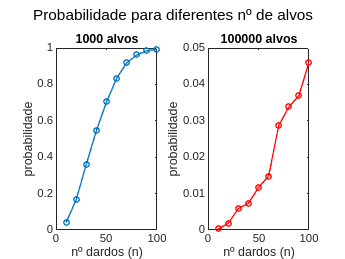

% nº de alvos
m1 = 1000;
m2 = 100000;

vetorLancamentos = 10:10:100;
matrizProbabilidades = zeros(2,10);

for nLanc = 1:length(vetorLancamentos)
    matrizDardos_c = randi(m1,vetorLancamentos(nLanc),10000); % nova matriz para novo nLancamentos
    casosFav_c = 0; % reset da variavel
    for i = 1:10000
        if length(matrizDardos_c(:,i)) > length(unique(matrizDardos_c(:,i)))
            casosFav_c = casosFav_c + 1;
        end
    end
    prob_c = casosFav_c/10000;
    matrizProbabilidades(1,nLanc) = prob_c;
end

for nLanc = 1:length(vetorLancamentos)
    matrizDardos_c = randi(m2,vetorLancamentos(nLanc),10000); % nova matriz para novo nLancamentos
    casosFav_c = 0; % reset da variavel
    for i = 1:10000
        if length(matrizDardos_c(:,i)) > length(unique(matrizDardos_c(:,i)))
            casosFav_c = casosFav_c + 1;
        end
    end
    prob_c = casosFav_c/10000;
    matrizProbabilidades(2,nLanc) = prob_c;
end

% grafico m1
subplot(1,2,1);
plot(vetorLancamentos, matrizProbabilidades(1,:), '-', 'Marker', 'o', 'MarkerSize', 4, 'LineWidth', 1);
title('1000 alvos');
xlabel('nº dardos (n)');
ylabel('probabilidade');

% grafico m2
subplot(1,2,2);
plot(vetorLancamentos, matrizProbabilidades(2,:), '-r', 'Marker', 'o', 'MarkerSize', 4, 'LineWidth', 1);

title('100000 alvos');
xlabel('nº dardos (n)');
ylabel('probabilidade');

sgtitle('Probabilidade para diferentes nº de alvos');

d)

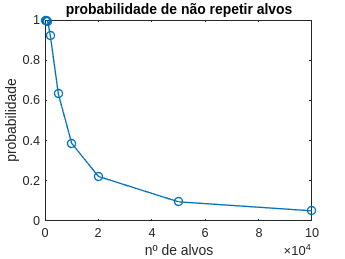

close all;  % sem esta linha o gráfico da d) aparece num subplot com o primeiro
            % gráfico anterior, não sei exatamente porquê
% nº de dardos = 100
% nº de alvos: 200, 500, 1000, 2000, 5000, 10000, 20000, 50000 e 100000
numExp = 10000;
vetorNumAlvos = [200, 500, 1000, 2000, 5000, 10000, 20000, 50000, 100000];
n = 100;
vetorProbabilidades = zeros(1,9);

for numAlvos = 1:length(vetorNumAlvos)
    matrizDardos_d = randi(vetorNumAlvos(numAlvos),n,numExp);
    casosFav_d = 0;
    for i = 1:10000
        if length(matrizDardos_d(:,i)) > length(unique(matrizDardos_d(:,i)))
            casosFav_d = casosFav_d + 1;
        end
    end
    vetorProbabilidades(numAlvos) = casosFav_d/numExp;
end

% gráfico
plot(vetorNumAlvos,vetorProbabilidades,'-o', LineWidth = 1);
title('probabilidade de não repetir alvos');
xlabel('nº de alvos');
ylabel('probabilidade');

%